# Main Document

*Authors:* Lili Baker, Olivia Chang, Tyler Ewald

*Learning Objectives:* As a result of working through this notebook, you will learn:

- put our learning objectives here

## Vaccine Model

Run me

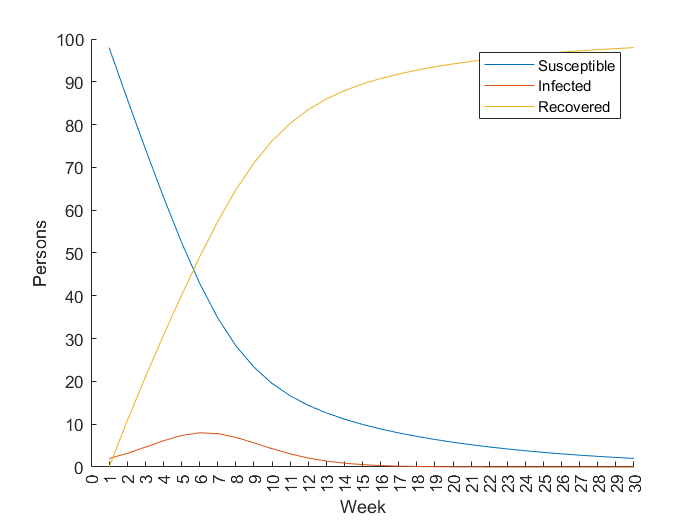

beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / week)
alpha = 0.1; % assume 10% of people are getting vaccinated in a given week
i_0 = 2;       % Initial count of infected persons

% Define initial state
s_0 = 100 - i_0;
r_0 = 0;

[S, I, R, W] = sir_vaccine(s_0, i_0, r_0, beta, gamma, alpha, 30);

% Plot
figure(1); clf; hold on;
xticks(0:1:40); % add axis ticks at a higher interval so we can see the weeks
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})